# Parcial 1

Juan E Gonzalez

## a)

 mi cedula termina en 0 por lo tanto trabajo sobre la montaña 1

## b)

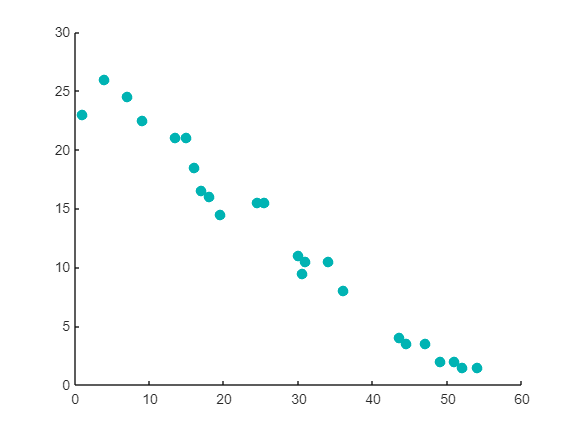

puntos=[
        1,23;
        4,26;
        7,24.5;
        9,22.5;
        13.5,21;
        15,21;
        16,18.5;
        17,16.5;
        18,16;
        19.5,14.5;
        24.5,15.5;
        25.5,15.5;
        30,11;
        30.5,9.5;
        31,10.5;
        34,10.5;
        36,8;
        43.5,4;
        44.5,3.5;
        47,3.5;
        49,2;
        51,2;
        52,1.5;
        54,1.5];

figure 
scatter(puntos(:,1), puntos(:,2),60,[0 .7 .7], 'filled')

## c)


sp=spl_c(puntos);
disp(sp)

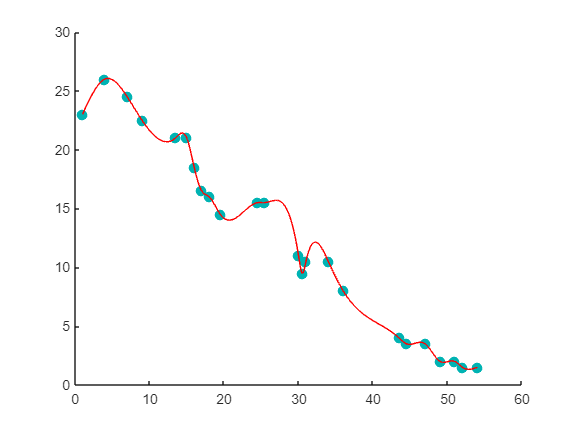

grf(sp,puntos);

## d)

22

disp(evalu(22,sp,puntos))

$$14.383783761531795414301271307522$$

40

disp(evalu(40,sp,puntos))

$$5.4703620731792014231231746634876$$

## e)

23

fun=sp-23;
resp=sp;
for i=1:numel(sp)
    resp(i)=falsi(puntos(i,1),puntos(i+1,1),fun(i),0.000001);
end
for i=1:numel(resp)
    if ~isnan(resp(i))
        disp(resp(i))
    end
end

$$1$$

$$8.4867903081814567564558429673241$$

14

fun=sp-14;
resp=sp;
for i=1:numel(sp)
    resp(i)=secn(puntos(i,1),puntos(i+1,1),fun(i),0.000001);
end
for i=1:numel(resp)
    if ~isnan(resp(i))
        disp(resp(i))
    end
end

$$28.995332649883935235433931418198$$

## Funciones)

function r=errror(a,b)
    r=abs((a-b)/b);
end
function resp=spl_c(puntos)
    syms x
    [num_points, ~] = size(puntos);
    s_num=num_points-1;
    k=4*(s_num);
    A=zeros(k);
    B=zeros(1,k);    
    t=0;
    for i=1:s_num
        in=((i-1)*4)+1;
        A(i,in)=1;
        B(i)= puntos(i, 2);
        t=t+1;
    end
    t=t+1;
    ult_x= puntos(s_num+1, 1);
    penult_x=puntos(s_num, 1);
    for i=1:4
        v=(ult_x-penult_x)^(i-1);
        in=(i+(4*(s_num-1)));
        A(t,in)=v;
        B(t)=puntos(s_num+1, 2);
    end
    t=t+1;
    for i=1:num_points-2
        xi=puntos(i, 1);
        xii=puntos(i+1, 1);
        for j=1:4
            v=(xii-xi)^(j-1);
            A(t,j+(i-1)*4)=v;
        end
        B(t)=B(i+1);
        t=t+1;
    end
    for i=1:num_points-2
        xi=puntos(i, 1);
        xii=puntos(i+1, 1);
        for j=2:4
            v=(j-1)*(xii-xi)^(j-2);
            A(t,(j+(i-1)*4))=v;
            
        end
        A(t,(j+(i-1)*4)+2)=-1;
        t=t+1;
    end
    for i=1:num_points-2
        xi=puntos(i, 1);
        xii=puntos(i+1, 1);
        for j=3:4
            v=2*(3^(j-3))*(xii-xi)^(j-3);
            A(t,(j+(i-1)*4))=v;
        end
        A(t,(j+(i-1)*4)+3)=-2;
        t=t+1;
    end
    A(t,3)=1;
    t=t+1;
    A(t,k-1)=2;
    A(t,k)=6*(ult_x-penult_x);
    array=inv(A)*transpose(B);
    ara=sym('x_%d_%d',[numel(array)/4 1]);
    for i =1:numel(array)/4
        a = array(4*i-3, 1);
        b = array(4*i-2, 1);
        c = array(4*i-1, 1);
        d = array(4*i, 1);
        ara(i)=a+b*(x-puntos(i,1))+c*((x-puntos(i,1))^2)+d*((x-puntos(i,1))^3);
    end
    resp=ara;
end
function val=evalu(v,arr,puntos)
    for i = 1:numel(arr)
        if (puntos(i,1)<v)&&(v<puntos(i+1,1))
            val=vpa(subs(arr(i),v));
        end
    end
end
function fig=grf(arr,puntos)
    figure
    scatter(puntos(:,1), puntos(:,2),60,[0 .7 .7], 'filled')
    hold on
    for i=1:numel(arr)
        fplot(arr(i),[puntos(i,1) puntos(i+1,1)],'r')
    end
    hold off
    fig=0;

end



function [sol,iter] = falsi(a,b, func, tolerancia)
    %disp(a)
    %disp(b)
    %disp(func)
    f_a = vpa(subs(func, a));
    f_b = vpa(subs(func, b));
    iter=0;
    i=0;
    if f_a*f_b < 0
        err = 1;
        while abs(err) > tolerancia
            c = b - f_b*(b-a)/(f_b-f_a);
            f_c = subs(func, c);
            if f_c == 0
                err = 0;
            elseif f_b*f_c < 0
                a = c;
                f_a = f_c;
                err = abs(f_c);
            elseif f_a*f_c < 0
                b = c;
                f_b = f_c;
                err = abs(f_c);
            end
            i=i+1;
        end
        iter=i;
        sol = c;
    elseif vpa(subs(func,a)) == 0
        sol = a;
    elseif vpa(subs(func,b)) == 0
        sol = b;
    else
        sol = NaN;
    end
end

function [resul, iter] = secn( p0, p1,func, tolerancia)
    f_0 = vpa(subs(func, p0));
    f_1 = vpa(subs(func, p1));
    iter = 0;
    if f_0*f_1 < 0
        err = 1;
        while err > tolerancia
            f_0 = vpa(subs(func, p0));
            f_1 = vpa(subs(func, p1));
            p2 = p1 - f_1*(p1-p0)/(f_1-f_0);
            f_2 = vpa(subs(func, p2));
            if f_2 == 0
                p1 = p2;
                err = 0;
            else
                p0 = p1;
                p1 = p2;
                err = errror(p0, p1);
            end
            iter = iter + 1;
        end
        resul = p1;
    elseif f_0 == 0
        resul = p0;
        iter = iter + 1;
    elseif f_1 == 0
        resul = p1;
        iter = iter + 1;
    else
        resul = NaN;
    end
end
